# Thermal simulation

BattMo support simulations with thermal coupling.

## Setup of the material properties

jsonfilename = fullfile('ParameterData'        , ...
                        'BatteryCellParameters', ...
                        'LithiumIonBatteryCell', ...
                        'lithium_ion_battery_nmc_graphite.json');
jsonstruct_material = parseBattmoJson(jsonfilename);

jsonstruct_material.include_current_collectors = true;

## Setup of the geometry

We use a simple 3d-geometry

jsonfilename = fullfile('Examples'     , ...
                        'JsonDataFiles', ...
                        'geometry3d.json');
jsonstruct_geometry = parseBattmoJson(jsonfilename);

## Setup of the Control

jsonfilename = fullfile('Examples', 'JsonDataFiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
                               jsonstruct_material , ...
                               jsonstruct_control}, 'warn', false);

In the json structure the value of the flag `use_thermal` is set to `true`, which means that the simulation will include thermal effects.

disp(jsonstruct.use_thermal);

   1



The thermal parameters are given for each component. They typically consists of

- Specific Heat Capacity

- Thermal Conducitivty

From those, we compute **effective** quantities. For the coating, it is done by processing the corresponding properties of the constituents. The effective thermal conductivity takes into account the volume fraction.

The parameters needed to compute the heat exchange with the exterior are

- The external temperature (K)

- The external heat transfer coefficient (W/m²/s)

The external heat transfer coefficient can take different values for each external face of the model. It will then depend on the chosen geometrical domain. For our simple 3D model, the json interface gives us the possibility to set two values : A default value used for all external faces which is overwritten by the value given for the tabs. In our example we use 100 W/m²/s and 1000 W/m²/s, respectively.

## Plot of the external heat transfer coefficient

We setup the model from the json struct input in order to inspect it. We could have run the simulation and retrieve from the output too.

model = setupModelFromJson(jsonstruct);

We retriecv index of the faces that are coupled thermally to the exterior

extfaceind = model.ThermalModel.couplingTerm.couplingfaces;
nf         = model.ThermalModel.G.getNumberOfFaces(); % total number of faces in the thermal model, which are in fact all the faces in the model

We create a vector with one value per face with value equal to the external heat transfer coefficient for the external face

val = NaN(nf, 1);
val(extfaceind) = model.ThermalModel.externalHeatTransferCoefficient;

We now use the function `plotFaceData` to plot the values of the external heat transfer coefficient on the faces of the 3d model.

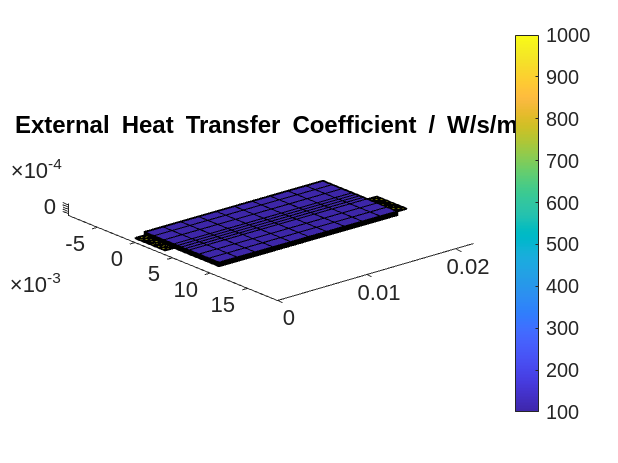

figure
plotFaceData(model.ThermalModel.grid, val, 'edgecolor', 'black');
axis equal
view([50, 20]);
title('External Heat Transfer Coefficient / W/s/m^2')
colorbar

## Run the simulation

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
| It # | ctrl_controlEquation (cell) | ne_cc_chargeCons (cell) | ctrl_EIequation (cell) | pe_cc_chargeCons (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) | thermal_energyCons (cell) |

## Plot of the voltage

We obtain the usual discharge curves and plot them.

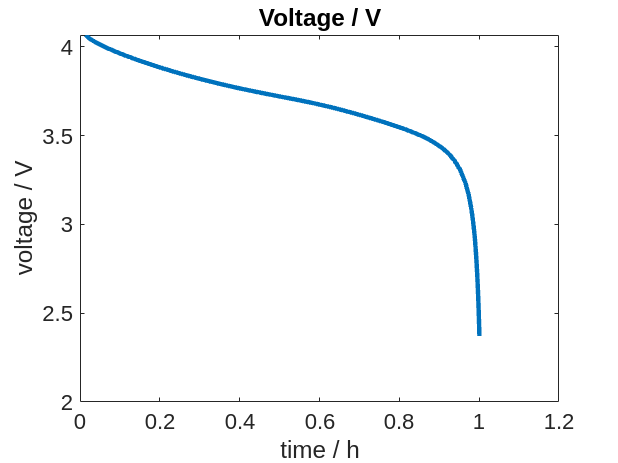

time = output.time;
E    = output.E;

set(0, 'defaulttextfontsize', 15);
set(0, 'defaultaxesfontsize', 15);
set(0, 'defaultlinelinewidth', 3);

figure
plot(time/hour, E)
title('Voltage / V');
xlabel('time / h');
ylabel('voltage / V');

## Plot of the minimum and maximum values of the temperature

We extract the temperature results and the minimum and maximum values from the output

T0 = PhysicalConstants.absoluteTemperature;

states = output.states;

Tmin = cellfun(@(state) min(state.ThermalModel.T + T0), states);
Tmax = cellfun(@(state) max(state.ThermalModel.T + T0), states);

We plot the values

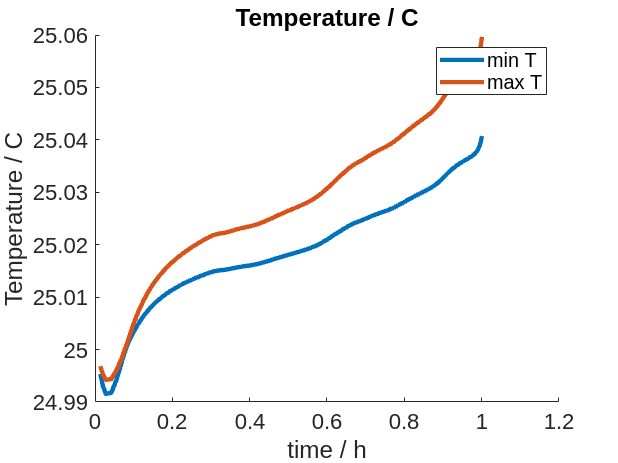

figure
hold on
plot(time / hour, Tmin, 'displayname', 'min T');
plot(time / hour, Tmax, 'displayname', 'max T');
title('Temperature / C')
xlabel('time / h');
ylabel('Temperature / C');

legend show

We notice that there is very little temperature variation. The reason is that we have a small cell which is very thin, with a lot of external contact where heat can be released.

Let us use a different heat exchange coefficient. We set the default heat exchange to zero so that heat exchange can only occur through the tabs.

## We change setup for cooling coefficient

jsonstruct.ThermalModel.externalHeatTransferCoefficientTab = 100;
jsonstruct.ThermalModel.externalHeatTransferCoefficient = 0;

We re-run the simulation and obtain higher temperatures.

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
| It # | ctrl_controlEquation (cell) | ne_cc_chargeCons (cell) | ctrl_EIequation (cell) | pe_cc_chargeCons (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) | thermal_energyCons (cell) |

## Plot of temperatures

We plot the minimum and maximum values of the temperature for the new values of the cooling coefficients

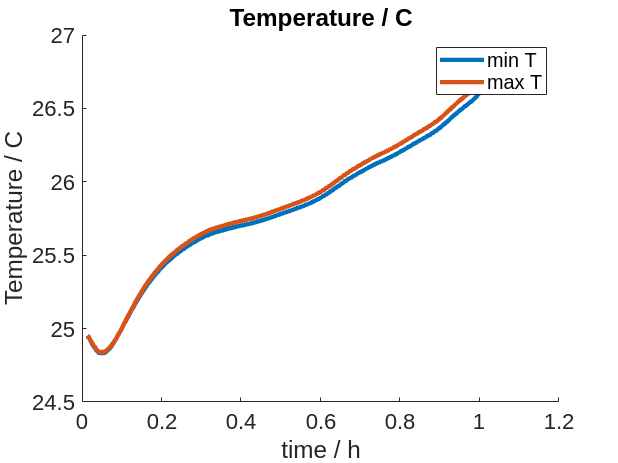

states = output.states;

Tmin = cellfun(@(state) min(state.ThermalModel.T + T0), states);
Tmax = cellfun(@(state) max(state.ThermalModel.T + T0), states);
time = output.time;

figure
hold on
plot(time / hour, Tmin, 'displayname', 'min T');
plot(time / hour, Tmax, 'displayname', 'max T');
title('Temperature / C')
xlabel('time / h');
ylabel('Temperature / C');

legend show

## Plot of the temperature distribution

We have access to the temperature distribution for all the cells in the model. Let us plot the temperature field for the last time step. To do so, we run

state = states{end}

state = struct with fields:
    NegativeElectrode: [1x1 struct]
    PositiveElectrode: [1x1 struct]
          Electrolyte: [1x1 struct]
         ThermalModel: [1x1 struct]
              Control: [1x1 struct]
                 time: 3.6023e+03


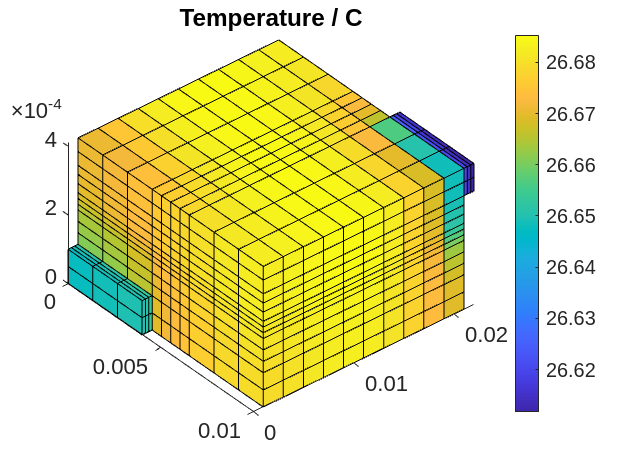

figure
plotCellData(model.ThermalModel.grid, ...
             state.ThermalModel.T + T0);
colorbar
title('Temperature / C');
view([50, 50]);